# **FORÅR 2017 REEKSAMEN**

***MADS STEINER KRISTENSEN -  201405230***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

clc
clear

addpath('[0] Library');
Color = load("colors.mat");
smp = load("library.mat");

# **1 STOKASTISKE VARIABLE**

En kontinuert stokastisk variabel $X$har følgende fordelingsfunktion $F_X \left(x\right)$.

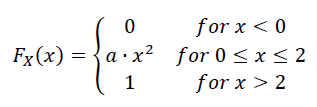

## 1.1 GYLDIG FORDELINGSFUNKTION

For at bestemme om $F_X \left(x\right)$ er en gyldig fordelingsfunktion anvendes, at for $x>2$ er $F_X \left(x\right)=1$, hvormed 


$$a\cdot x^2 =1,\;\mathrm{hvor}\;\;x=2$$


syms Fx(x) a
Fx(x) = piecewise(x<0, 0, (0<=x) & (x<=2), a*x^2, x>2, 1);

Eq = int(diff(Fx(x)), -inf, inf) == 1

$$Eq = 4\,a=1$$

solve(Eq, a)

$$ans = \frac{1}{4}$$

 $F_X \left(x\right)$ er en gyldig tæthedsfunktione for værdien af $a$ lig med $\frac{1}{4}\ldotp$

## 1.2 TÆTHEDSFUNKTION

For at finde tæthedsfunktionen anvendes, at


$$f_X \left(x\right)=\frac{\textrm{d}}{\textrm{d}x}F_X \left(x\right)$$


syms Fx(x)
a = 1/4;
Fx(x) = piecewise(x<0, 0, (0<=x) & (x<=2), a*x^2, x>2, 1)

$$Fx(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<0\\ \frac{x^{2}}{4} & \text{ if }x\in \left[0,2\right]\\ 1 & \text{ if }2<x \end{array}\right.$$

Tæthedsfunktionen $f_X \left(x\right)$hermed bestemt til at være


$$f_X \left(x\right)=\left\lbrace \left\lbrack \begin{array}{cc}
0 & x<0\\
2a\cdot x=\frac{1}{2}x & 0\le x\le 2\\
0 & x>2
\end{array}\right\rbrack \right\rbrace$$


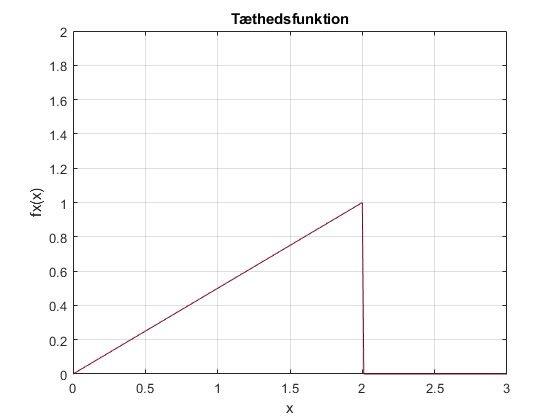

syms fx(x) 
fx(x) = piecewise(x<0, 0, (0<=x) & (x<=2), 1/2*x, x>2, 0);
x = 0:0.01:3;

figure(1)
plot(x, fx(x), 'Color', Color.DeepCleret);
grid on
title('Tæthedsfunktion')
ylabel('fx(x)')
xlabel('x')
axis([0, 3, 0, 2]);

## 1.3 SANDSYNLIGHED 

For at bestemme sandsynligheden for $1\le X\le 2$ anvendes, at


$$P\left(a\le X\le b\right)=\int_a^b f_X \left(x\right)\mathrm{dx}$$


Da $f_X \left(x\right)$ i intervallet fra 1 til 2 er lig med $\frac{1}{2}x$, vides at


$$\int_1^2 f_X \left(x\right)\mathrm{dx}$$


clear x
xpdf = @(x) 1/2*x;

integral(xpdf, 1, 2)

ans = 0.7500

Sandsynligheden er dermed bestemt til at være 0.75 altså 75%.

## 1.4 MIDDELVÆRDI OG VARIANS

For at bestemme forvetningsværdien anvendes, at 


$$E\left\lbrack X\right\rbrack =\bar{X} =\mu_x =\int_{-\infty }^{\infty } x\cdot f_x \left(x\right)\mathrm{dx}=\int_0^2 x\cdot \frac{1}{2}\cdot x\;\mathrm{dx}$$


hvor værdien for $a$ antages, at være $\frac{1}{4}$.

a = 1/4;
xpdf = @(x) x .* 1/2.*x;
EstimationValue = sym(integral(xpdf, 0, 2))

$$EstimationValue = \frac{4}{3}$$

Forventningsværdien er dermed bestemt til, at være $\frac{4}{3}$. Variansen bestemmes dernæst ved følgende,


$$\mathrm{Var}\left(x\right)=\int_{-\infty }^{\infty } \left(x-\bar{x} \right)\cdot f_X \left(x\right)\mathrm{dx}=E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


fx = @(x) x.^2 * 1/2.*x;
Variance = sym(integral(fx, 0, 2)) - EstimationValue^2

$$Variance = \frac{2}{9}$$

Variansen er dermed bestemt til, at være $\frac{2}{9}$.

# **2 SANDSYNLIGHED**

En leverance af modstande indeholder

Modstandene leveres både som 5% modstande og 1% modstande. 1% modstandene udgør ¼ af 1 kΩ, ½ af 10 kΩ og ¾ af 100 kΩ modstandene. Modstandene er desværre blevet blandet sammen og leveres i én blandet pose.


$$A_1 :1k\Omega$$
  
$$A_{10} :10k\Omega$$
   
$$A_{100} :100k\Omega$$



$$B_1 :1%$$
   
$$B_5 :5%$$



$$P\left(B_1 |A_1 \right)=\frac{1}{4}$$



$$P\left(B_1 |A_{10} \right)=\frac{1}{2}$$



$$P\left({B_1 |A}_{100} \right)=\frac{3}{4}$$


BOneGivenAOne = 1/4;
BOneGivenATen = 1/2;
BOneGivenAHundred = 3/4;

ROne = 1000;
RTen = 800;
RHundred = 400;

Resistors = ROne + RTen + RHundred;

## 2.1 UDTAGNE MODSTAND

For at bestemme sandsynlighede for hvilken modstand der trækkes anvendes, at


$$P\left(A\right)=\frac{N_s }{N}$$


Resistor.One = ROne / Resistors;
Resistor.Ten = RTen / Resistors;
Resistor.Hundred = RHundred / Resistors;

Resistor

Resistor = struct with fields:
        One: 0.4545
        Ten: 0.3636
    Hundred: 0.1818


Sandsynligheden for at trække hhv. 1, 10 eller 100 kilohms modstand er vist i ovenstående.

## 2.2 MODSTAND

For at bestemme sandsynligheden for, at modstanden er både $10k\Omega$ og 1% anvendes, at


$$P\left(A_{10} \cap B_1 \right)=P\left(B_1 |A_{10} \right)\cdot P\left(A_{10} \right)$$


ATenAndBOne = BOneGivenATen * Resistor.Ten

ATenAndBOne = 0.1818

Sandsynligheden er dermed bestemt til at være 0.1818 altså 18.18%.

## 2.3 MODSTAND 1 PROCENT

For at bestemme sandsynligheden for at den udtagne modstand er 1% anvendes, at


$$P\left(A\right)=\sum_{i=1}^n P\left(A|B_i \right)\cdot P\left(B_i \right)$$


BOne = BOneGivenAOne * Resistor.One + BOneGivenATen * Resistor.Ten + BOneGivenAHundred * Resistor.Hundred

BOne = 0.4318

Sandsynligheden er dermed bestemt til at være 0.4318 altså 43.18%.

## 2.4 MODSTAND 5 PROCENT

For at bestemme sandsynligheden for at modstanden er $100k\Omega$ givet at den er 5% anvendes, at


$$P\left(A_{100} |B_5 \right)=\frac{P\left(B_5 |A_{100} \right)\cdot P\left(A_{100} \right)}{P\left(B_5 \right)}$$


BFive = 1 - BOne;
BFiveGivenAHundred = 1 - BOneGivenAHundred;

AHundredGivenFive = (BFiveGivenAHundred * Resistor.Hundred) / BFive

AHundredGivenFive = 0.0800

Sandsynligheden er dermed bestemt til at være 0.08 altså 8.00%.

# **3 STOKASTISK PROCESS**

En diskret stokastisk process $X\left(n\right)$er givet ved


$$X\left(n\right)=2\cdot W\left(n\right)-1$$


hvor $W\left(n\right)$ er i.i.d fordelte efter

## 3.1 REALISERING

Realisering af den diskrete process er lavet i Matlab.

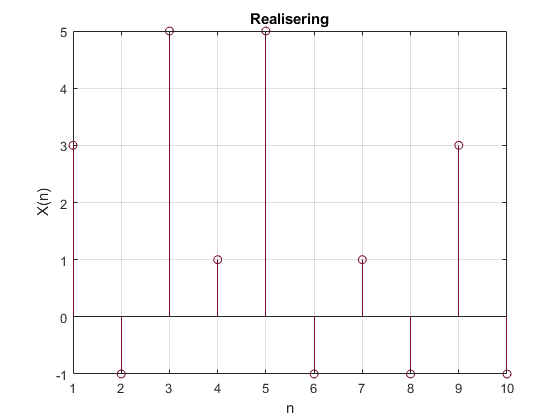

X = 2 * (unidrnd(4, 1, 10) - 1) - 1;
n = 1:1:10;

figure(1)
stem(n, X, 'o', 'Color', Color.DeepCleret);
grid on
title('Realisering')
ylabel('X(n)')
xlabel('n')
hold off

## 3.2 REALISERING MIDDELVÆRDI OG VARIANS

Real.Mean = mean(X);
Real.Variance = round(var(X), 10);

Real

Real = struct with fields:
        Mean: 1.4000
    Variance: 6.0444


## 3.3 MIDDELVÆRDI OG VARIANS

For at bestemme middelværdien for processen anvendes, at 


$$E\left(\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack 2\cdot W\left(n\right)-1\right\rbrack =2\cdot E\left\lbrack W\left(n\right)\right\rbrack -1\right.$$


Hvor $W\left(n\right)$er uniform og dermed gælder, at 


$$E\left\lbrack W\left(n\right)\right\rbrack =\frac{a+b}{2}$$


hvor $a=0$ og $b=3$

a = 0;
b = 3;

MeanValue = 2 * ((a+b)/2) - 1

MeanValue = 2

Middelværdien er dermed bestemt til at være 2. For variansen gælder, at


$$\mathrm{Var}\left\lbrack X\left(n\right)\right\rbrack =\mathrm{Var}\left\lbrack 2\cdot W\left(n\right)-1\right\rbrack =2^2 \cdot \mathrm{Var}\left\lbrack W\left(n\right)\right\rbrack$$



$$\mathrm{Var}\left\lbrack W\left(n\right)\right\rbrack =\frac{1}{12}{\left(b-a\right)}^2$$


Variance = 2^2 * ((1/12)*((b-a+1)^2 - 1))

Variance = 5

## 3.4 PROCESSEN

Processen er WSS da middelværdi og varians er uafhængig af tiden. Da Middelværdi og varians kan bestemmes ud fra en realisering er processen ergodisk.

# **4 STATISTIK**

For en bestemt type batterier angives i specifikationen fra leverandøren, at levetiden T for batterierne er normalfordelt med en middellevetid på 3000 timer med en standard afvigelse på 100 timer: $T\sim N\left(3000,{100}^2 \right)$. Der udtages tilfældigt 12 batterier af pågældende type. Ved en test måles levetiden af disse til:

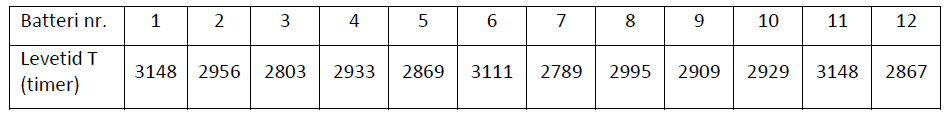

## 4.1 HYPOTESE

Der opstilles en hypotese test for at bestemme om middelværdien af levettiden er lig med middel af de målte levetid.


$$H_0 :$$
  
$$\mu_T =T=3000$$



$$H_1 :$$
  
$$\mu_t \not= T=3000$$


## 4.2 MIDDELVÆRDI

For at bestemme den estimerede middelværid af batteri levetiden anvendes, at 


$$\overline{x} =\mu^ˆ =\frac{1}{n}\sum_{i=1}^n x_i$$


Battery = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12];
Lifetime = [3148, 2956, 2803, 2933, 2869, 3111, 2789, 2995, 2909, 2929, 3148, 2867];

MeanLifeTime = (1 / length(Battery)) * sum(Lifetime) 

MeanLifeTime = 2.9548e+03

Den estimerede middellevetid for et batteri er bestemt til at være 2453.5.

## 4.3 Z-TEST

Der laves en z-test hvor der gælder, at


$$Z=\frac{\overline{x} -\mu }{\frac{\sigma }{\sqrt{n}}}$$


sigma = 100;

Z = (MeanLifeTime - 3000) / (sigma / sqrt(length(Battery)))

Z = -1.5675

Z er dermed bestemt til at være -1.5675. For at bestemme om NULL hypotesen kan afvises findes p-værdien.

p = 2 * abs(1 - normcdf(abs(Z), 0, 1))

p = 0.1170

Da p værdien er større end 0.05 kan null hypotesen ikke afvises.

## 4.4 KONFIDENSINTERVAL

For at bestemme 95% konfidensintervallet anvendes, at 


$$\mu_{\pm } =\overline{x} \pm 1\ldotp 96\cdot \frac{\sigma }{\sqrt{n}}$$


delta = 1.96 * (sigma / sqrt(length(Battery)));

mu.min = MeanLifeTime - delta;
mu.max = MeanLifeTime + delta;

mu

mu = struct with fields:
    min: 2.8982e+03
    max: 3.0113e+03


Konfidensintervallet for $\mu$ er dermed bestemt til at være [2898.2; 3011.3].